# Ejercicio 1: Metodo de Biseccion

f = @(x) -x^2 + 2 *x + exp(x)

f = function_handle with value:
    @(x)-x^2+2*x+exp(x)


a = -1

a = -1

b = 0

b = 0

niter = 10

niter = 10

# Teorema de Bolzano

if f(a) * f(b) < 0
    disp('Existe almenos una raiz')
else
    disp('No se puede afirmar algo')
end

Existe almenos una raiz


# Metodo Grafico

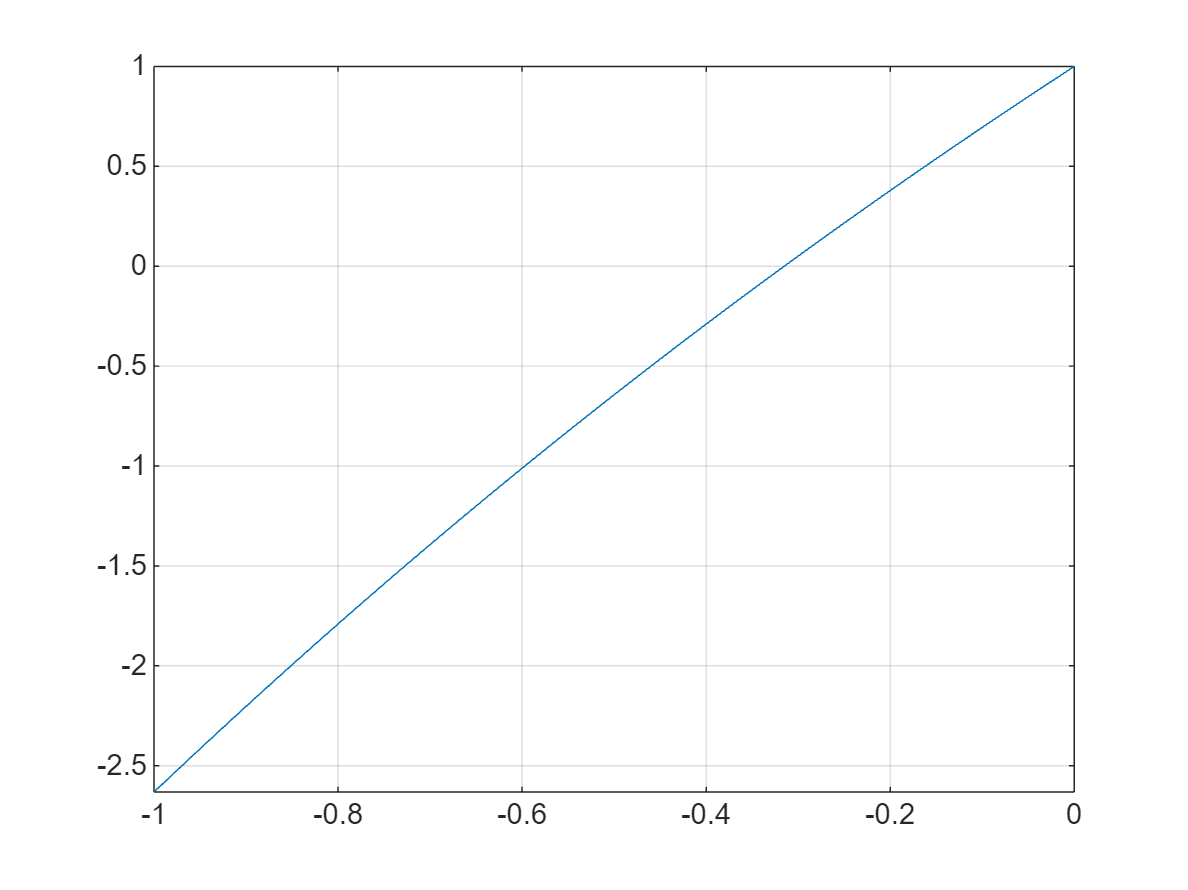

fplot(f,[a,b]), grid on

# Metodo de Biseccion:

c = (a + b)/ 2

c = -0.5000

if f(c) * f(a) > 0
    a = c;
else
    b = c;
end
a,b

a = -0.5000

b = 0

c = (a + b) / 2

c = -0.2500

# Metodo de Biseccion

c = (a + b ) / 2;
ea = (b-a)/2

ea = 0.2500

i = 0

i = 0

z = [i a c b f(a) f(c) f(a)*f(c) ea]

z =          0   -0.5000   -0.2500         0   -0.6435    0.2163   -0.1392    0.2500



for i = 1:niter
    if f(c) * f(a) > 0
        a = c;
    else
        b = c;
    end
    c = (a + b ) / 2;
    z = [z;i a c b f(a) f(c) f(a)*f(c) ea];
end

disp(c)

   -0.3152



disp(z)

         0   -0.5000   -0.2500         0   -0.6435    0.2163   -0.1392    0.2500
    1.0000   -0.5000   -0.3750   -0.2500   -0.6435   -0.2033    0.1308    0.2500
    2.0000   -0.3750   -0.3125   -0.2500   -0.2033    0.0090   -0.0018    0.2500
    3.0000   -0.3750   -0.3438   -0.3125   -0.2033   -0.0966    0.0196    0.2500
    4.0000   -0.3438   -0.3281   -0.3125   -0.0966   -0.0436    0.0042    0.2500
    5.0000   -0.3281   -0.3203   -0.3125   -0.0436   -0.0173    0.0008    0.2500
    6.0000   -0.3203   -0.3164   -0.3125   -0.0173   -0.0042    0.0001    0.2500
    7.0000   -0.3164   -0.3145   -0.3125   -0.0042    0.0024   -0.0000    0.2500
    8.0000   -0.3164   -0.3154   -0.3145   -0.0042   -0.0009    0.0000    0.2500
    9.0000   -0.3154   -0.3149   -0.3145   -0.0009    0.0008   -0.0000    0.2500
   10.0000   -0.3154   -0.3152   -0.3149   -0.0009   -0.0001    0.0000    0.2500



# Ejercicio 2 : Metodo de NewTon

f = @(x) -x^2 + 2*x + exp(x);
x0 = 0;
Tol = 0.001;

%function z = newton(f,x0,Tol)
syms x
df = matlabFunction(diff(f,x));
dr = 1;
i = 0;
z = [i x0 dr];
while ( dr > Tol)
    x1 = x0 -f(x0)/df(x0);
    dr = abs(x1-x0) / abs(x1);
    i = i + 1;
    z = [z;i x1 dr];
    x0 = x1;
end

disp(z)

         0         0    1.0000
    1.0000   -0.3333    1.0000
    2.0000   -0.3152    0.0574
    3.0000   -0.3152    0.0002



f(x1)

ans = -2.4716e-09